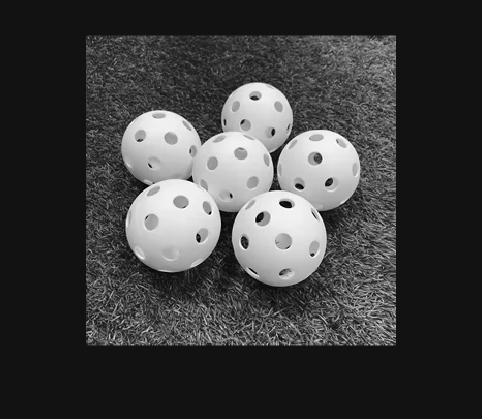

clear all;
close all;

img = imread('demo2.jpg');
gray = im2gray(img);
imshow(gray);

Find centers and radius of circles

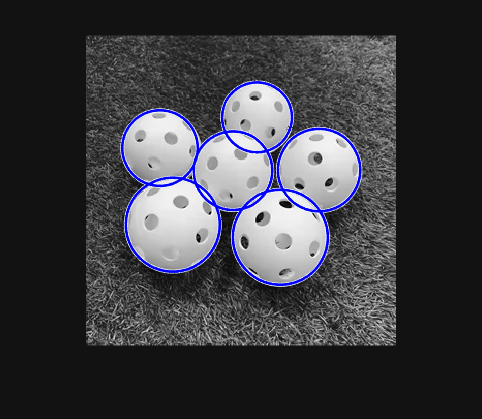

Rmin = 20;
Rmax = 100;
% Find bright objects
[centersBright, radiiBright] = imfindcircles(img, [Rmin Rmax], 'ObjectPolarity', 'bright', 'Sensitivity', 0.89);
% Find dark objects
[centersDark, radiiDark] = imfindcircles(img, [Rmin Rmax], 'ObjectPolarity', 'dark', 'Sensitivity', 0.91);
viscircles(centersBright, radiiBright, 'EdgeColor', 'b');